# Quadruped robot RL training tasks

## Prepare workspace

clear
clc
addpath("ExtParts\");
seedNum = 50;
rng(seedNum)

## Environment settings

Select env.

mdl = 'robotModelForPaper';
% robot animation on/off
set_param(mdl,'SimMechanicsOpenEditorOnUpdate','on') 

numAct = 12; % 12;
% Obs include: #rot x,y,z #v x,y,z #fn: FR,FL,RL,RR
numObs = 10 + numAct;

#### Define bending angle mapping

alpha_r_gain = pi;
alpha_b_gain = pi/6;
z_l_gain = 7e-3;
delta_gain = 0.2;

#### Robot run time

Tf = 5;
Ts = 0.05;

#### Obs noises

% added in amplitude 1
rotVariance = 0.002; % 0.001
fnVariance = 0.005; % 0.002
speedVariance = 0.002; % 0.001

## Training settings

#### Target speed

VRef = 0.15; % reference velocity

#### Actor-Critic learning settings

criticLearnRate = 2e-3;
actorLearnRate = 1e-3;

DiscountFactor = 0.96;
TargetSmoothFactor = 1e-3;

ExperienceBufferLength = 1024;
MiniBatchSize = 256;

EntropyWeight = 1;
EntropyLearnRate = 1e-4;
TargetEntropy = -numAct*1;

maxEpisodes = 1500;

maxSteps = floor(Tf/Ts);

SaveAgentReward = 75;
StopTrainReward = 150;

% !!! For continued/curriculum training -->
% !!!Change dir to run1,2,3 to avoid overlapping saved agents
SaveAgentDir = "C:\Users\4DLab5\OneDrive - KTH\KTH\Master Thesis\Github\MBRL23KTH\savedAgents";

if ~exist(SaveAgentDir, 'dir')
    mkdir(SaveAgentDir)
end

UseParallel = 0;
numsWorkers = 3;

#### Overall training settings

doTraining = 1; % if not train, noise is disabled
isUseExtAct = 0;
startAgentTime = 0*Tf/10;
isCheckDone = 1;
isContactBoolean = 0;

% !!! for continued training -->
% !!! Change the value to 1 and update the latest agent!
isUsePretrainedAgent = 0;
pretrainedAgent = SaveAgentDir + "\agent1107.mat";
% !!! for curriculum training -->
% !!! for now (1224), use agent : 
%  "savedAgents\Agent035ForCurriculum\agent035.mat"

## Create environment info

actInfo = rlNumericSpec([numAct 1],'LowerLimit',0,'UpperLimit', 1);
actInfo.Name = 'actions';

obsInfo = rlNumericSpec([numObs 1]);
obsInfo.Name = 'observations';

blk = [mdl, '/RL Agent'];
env = rlSimulinkEnv(mdl,blk,obsInfo,actInfo,'UseFastRestart','on');


Create storage for entropy record and episode number

% EpiCount = 0;
% instantTrainingStats = [];
entropyListSize = maxSteps*maxEpisodes;
EntropyList = zeros(entropyListSize, 1);
EntropyList(1)=TargetEntropy;

EntropyWeightList = zeros(entropyListSize, 1);
EntropyWeightList(1)=EntropyWeight;

## Specify agent training options (parallel training try)

maxSteps = floor(Tf/Ts);  

trainOpts = rlTrainingOptions(...
    'UseParallel', true, ...
    'MaxEpisodes',maxEpisodes,...
    'MaxStepsPerEpisode',maxSteps,...
    'ScoreAveragingWindowLength',10,...
    'Verbose',true,...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',StopTrainReward,...                   
    'SaveAgentCriteria','EpisodeReward',... 
    'SaveAgentValue',SaveAgentReward,...
    'SaveAgentDirectory', SaveAgentDir);

trainOpts.UseParallel = UseParallel;
if trainOpts.UseParallel == true
    delete(gcp('nocreate'));
    parpool(numsWorkers); % specify the number of workers
    %set_param(mdl,'SimMechanicsOpenEditorOnUpdate','off')
    trainOpts.ParallelizationOptions.Mode = 'async';
    trainOpts.ParallelizationOptions.StepsUntilDataIsSent = -1;
    trainOpts.ParallelizationOptions.DataToSendFromWorkers = 'Experiences';
end

## Create or load agent

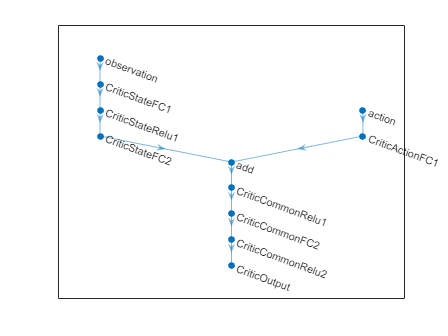

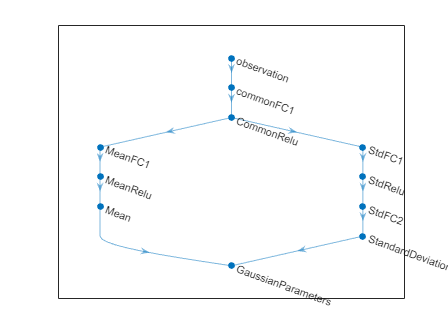

if isUsePretrainedAgent
    load(pretrainedAgent)
    if exist('saved_agent','var')
        agent = saved_agent;
    end
else
    createAgent
end

## Train or test agent

if doTraining
    save_system(mdl)
    trainingStats = train(agent,env,trainOpts);
    
    % !!! RUN the following lines to save current agent and workspace!
    currentTimestr = datestr(now,'yyyy_mmmm_dd_HH_MM');
    save(append(SaveAgentDir,'\agent_', currentTimestr,'.mat'),'agent');
    save(append(SaveAgentDir,'\workspace_seedNum',num2str(seedNum),'_', currentTimestr,'.mat'));
    %---------------------%
else
    %rotVariance = 0;
    %fnVariance = 0;
    %speedVariance = 0;
    agent.AgentOptions.UseDeterministicExploitation = 1;

    randObs = {rand(obsInfo(1).Dimension)};
    DistributionParams = evaluate(agent.Actor, randObs);
    DistributionParams = DistributionParams{1};

    figure('Name','Current agent info. with a randObs','NumberTitle','off')
    set(gcf,'Visible','on')
    subplot(3,1,1)
    plot(DistributionParams(1:12),'LineWidth',2)
    xticks(1:1:12)
    xlabel('Action number')
    ylabel('Action distribution mean')
    hold off
    
    subplot(3,1,2)
    plot(DistributionParams(13:24),'LineWidth',2)
    xticks(1:1:12)
    xlabel('Action number')
    ylabel('Action distribution std')
    hold off

    subplot(3,1,3)
    for i = 1:1:50
        actionOut = getAction(agent,randObs);
        plot(actionOut{1},'LineWidth',1)
        hold on
    end
    xticks(1:1:12)
    xlabel('Action number')
    ylabel('Action for a randObs')
    hold off

    tic
    simout = sim(mdl);
    toc

    figure('Name','Robot body information','NumberTitle','off')
    set(gcf,'Visible','on')
    subplot(4,1,1)
    plot(simout.Reward.time, simout.Reward.signals.values,'LineWidth',2)
    xlabel('Time (s)')
    ylabel('Reward')
    hold off
    
    subplot(4,1,2)
    hold on
    plot(simout.Observations.x.Time, simout.Observations.x.Data,'LineWidth',2)
    plot(simout.Observations.y.Time, simout.Observations.y.Data,'LineWidth',2)
    plot(simout.Observations.z.Time, simout.Observations.z.Data,'LineWidth',2)
    legend('x','y','z')
    xlabel('Time (s)')
    ylabel('position (m)')
    hold off
    
    subplot(4,1,3)
    hold on
    plot(simout.Observations.vx.Time, simout.Observations.vx.Data,'LineWidth',2)
    plot(simout.Observations.vy.Time, simout.Observations.vy.Data,'LineWidth',2)
    plot(simout.Observations.vz.Time, simout.Observations.vz.Data,'LineWidth',2)
    legend('vx','vy','vz')
    xlabel('Time (s)')
    ylabel('Speed (m/s)')
    hold off
    
    subplot(4,1,4)
    
    rotData = reshape(simout.Observations.rot.Data,size(simout.Observations.rot.Data,[1,3]));
    hold on
    plot(simout.Observations.rot.Time, rotData(1,:),'LineWidth',2)
    plot(simout.Observations.rot.Time, rotData(2,:),'LineWidth',2)
    plot(simout.Observations.rot.Time, rotData(3,:),'LineWidth',2)
    legend('rotX','rotY','rotZ')
    xlabel('Time (s)')
    ylabel('Rotate (rad)')
    hold off
    
    figure('Name','Robot leg information','NumberTitle','off')

    windowSize = 1; 
    b = (1/windowSize)*ones(1,windowSize);
    a = 1;

    set(gcf,'Visible','on')
    subplot(4,1,1)
    hold on
    plot(simout.Observations.SigsFromLegs.FnFR.Time,simout.Observations.SigsFromLegs.FnFR.Data,'LineWidth',2)
    plot(simout.Observations.SigsFromLegs.FnFL.Time,simout.Observations.SigsFromLegs.FnFL.Data,'LineWidth',2)
    plot(simout.Observations.SigsFromLegs.FnRR.Time,simout.Observations.SigsFromLegs.FnRR.Data,'LineWidth',2)
    plot(simout.Observations.SigsFromLegs.FnRL.Time,simout.Observations.SigsFromLegs.FnRL.Data,'LineWidth',2)
    legend('FnFR','FnFL','FnRR','FnRL')
    xlabel('Time (s)')
    ylabel('Contact force (N)')
    hold off
    
    subplot(4,1,2)
    hold on
    bendFRData = reshape(simout.Observations.SigsFromLegs.bendFR.Data,size(simout.Observations.SigsFromLegs.bendFR.Data,[1,3]));
    plot(simout.Observations.SigsFromLegs.bendFR.Time,filter(b,a,bendFRData(2,:)),'LineWidth',2)
    bendFLData = reshape(simout.Observations.SigsFromLegs.bendFL.Data,size(simout.Observations.SigsFromLegs.bendFL.Data,[1,3]));
    plot(simout.Observations.SigsFromLegs.bendFL.Time,filter(b,a,bendFLData(2,:)),'LineWidth',2)
    bendRRData = reshape(simout.Observations.SigsFromLegs.bendRR.Data,size(simout.Observations.SigsFromLegs.bendRR.Data,[1,3]));
    plot(simout.Observations.SigsFromLegs.bendRR.Time,filter(b,a,bendRRData(2,:)),'LineWidth',2)
    bendRLData = reshape(simout.Observations.SigsFromLegs.bendRL.Data,size(simout.Observations.SigsFromLegs.bendRL.Data,[1,3]));
    plot(simout.Observations.SigsFromLegs.bendRL.Time,filter(b,a,bendRLData(2,:)),'LineWidth',2)
    legend('bendFR','bendFL','bendRR','bendRL')
    xlabel('Time (s)')
    ylabel('Bending angle (rad)')
    hold off
    
    subplot(4,2,5)
    hold on
    plotStartStep = 1; %find(simout.FLfootTrace.Time > (startAgentTime-0.9), 1);
    plotEndStep = size(simout.FLfootTrace.Time,1); % find(simout.FLfootTrace.Time > (startAgentTime-0.1), 1);
    plot(simout.FLfootTrace.Data(plotStartStep:plotEndStep,1),simout.FLfootTrace.Data(plotStartStep:plotEndStep,3),'LineWidth',2)
    legend('FL foot trace')
    xlabel('x (m)')
    ylabel('z (m)')
    hold off

    subplot(4,2,6)
    hold on
    plot(simout.FRfootTrace.Data(plotStartStep:plotEndStep,1),simout.FRfootTrace.Data(plotStartStep:plotEndStep,3),'LineWidth',2)
    legend('FR foot trace')
    xlabel('x (m)')
    ylabel('z (m)')
    hold off

    subplot(4,2,7)
    hold on
    plot(simout.RLfootTrace.Data(plotStartStep:plotEndStep,1),simout.RLfootTrace.Data(plotStartStep:plotEndStep,3),'LineWidth',2)
    legend('RL foot trace')
    xlabel('x (m)')
    ylabel('z (m)')
    hold off

    subplot(4,2,8)
    hold on
    plot(simout.RRfootTrace.Data(plotStartStep:plotEndStep,1),simout.RRfootTrace.Data(plotStartStep:plotEndStep,3),'LineWidth',2)
    legend('RR foot trace')
    xlabel('x (m)')
    ylabel('z (m)')
    hold off

end

Episode:   1/1500 | Episode reward:     8.40 | Episode steps:  100 | Average reward:     8.40 | Step Count:  100 | Episode Q0:    -0.11
Episode:   2/1500 | Episode reward:    -0.42 | Episode steps:  100 | Average reward:     3.99 | Step Count:  200 | Episode Q0:    -0.12
Episode:   3/1500 | Episode reward:    -1.17 | Episode steps:  100 | Average reward:     2.27 | Step Count:  300 | Episode Q0:    -0.18
Episode:   4/1500 | Episode reward:     0.01 | Episode steps:  100 | Average reward:     1.70 | Step Count:  400 | Episode Q0:    -0.24
Episode:   5/1500 | Episode reward:    12.58 | Episode steps:  100 | Average reward:     3.88 | Step Count:  500 | Episode Q0:    -0.25
Episode:   6/1500 | Episode reward:     6.54 | Episode steps:  100 | Average reward:     4.32 | Step Count:  600 | Episode Q0:    -0.79
